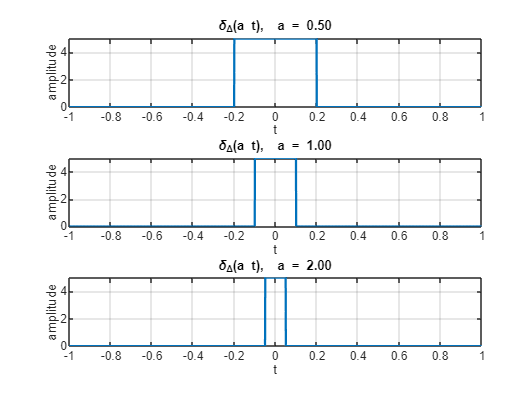


s     = @(t)   (t >= 0).*t;                       % rampa unidade
uD    = @(t,D) (1./D) .* (s(t + D/2) - s(t - D/2));  % step "suave" u_Δ
duD   = @(t,D,h) (uD(t+h/2,D) - uD(t-h/2,D)) ./ h;   % derivada numérica
deltaD = @(t,D) duD(t,D,1e-6);                       % impulso aproximado

D = 0.2;
t = -1:0.0005:1;

a_vals = [0.5, 1, 2];

figure;
for i = 1:length(a_vals)
    a = a_vals(i);
    subplot(length(a_vals),1,i);
    plot(t, deltaD(a*t,D), 'LineWidth', 1.5); % n consigo perceber porque é que n esta a dar bem
    grid on;
    title(sprintf('\\delta_{\\Delta}(a t),  a = %.2f', a));
    xlabel('t'); ylabel('amplitude');
end